## Задание 1

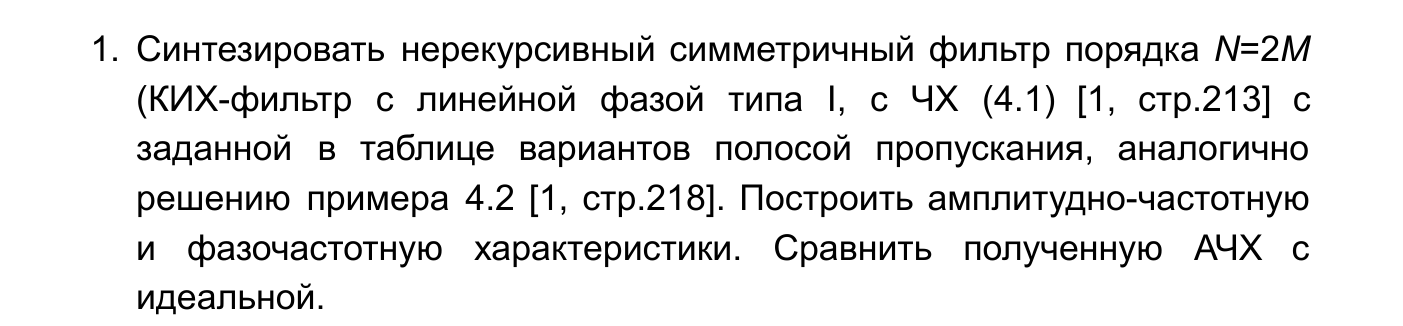

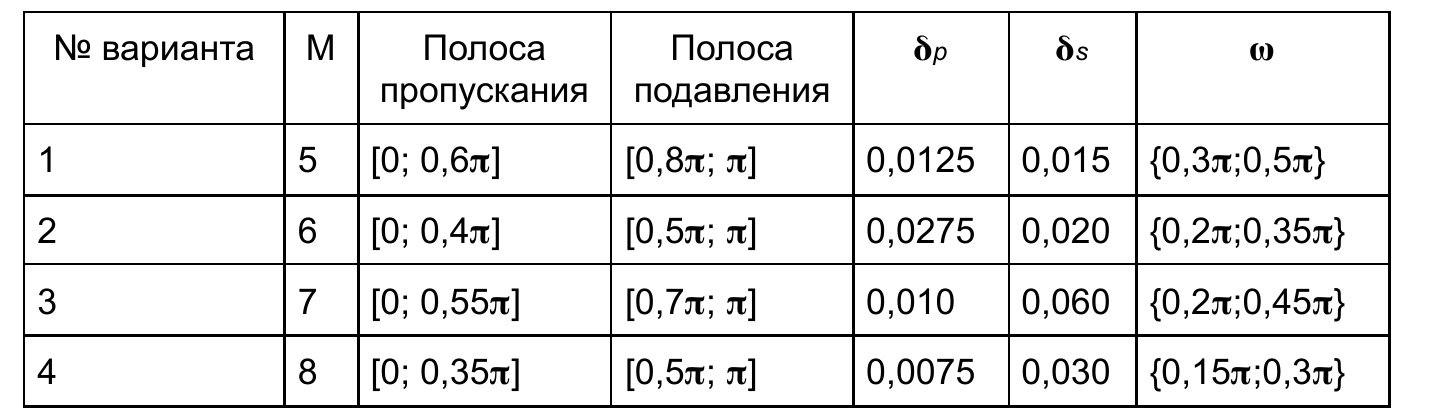

Параметры:

clear;
w = -2*pi:0.001:2*pi;
w_p = [0 0.35*pi]; % bandwidth
w_s = [0.5*pi pi]; % suppress

Построение фиьтра:

% filter parameters
M = 8;
w_j = pi * ((0:M) + 0.5)/(M + 1);
K_d = (w_j >= w_p(1) & w_j < w_p(2));

% calculation of filter coefficients by formula (4.8)
h = zeros(1, M + 1);
for k = 0:M
    for j = 0:M-1
        h(M - k + 1) = h(M - k + 1) + K_d(j+1) * cos(pi * k * (j + 0.5) / (M+1)); % see (4.8)
    end
    h(M - k + 1) = h(M - k + 1)/(M + 1);
end


% calculating the frequency response, see (4.1) and (4.7)
A = zeros(1,length(w));
for i = 0:length(w)-1
    A(i + 1) = h(M + 1);
    for k = 1:M
        A(i + 1) = A(i + 1) + 2*(h(M - k + 1) * cos(w(i + 1)*k)); % see (4.7)
    end
    A(i + 1) = A(i + 1) * exp(-1i * w(i + 1) * M);  % see (4.1)
end

Идеальный фильтр

A_ideal = zeros(1,length(w));
for i = 1:length(w)
    w_i = abs(sign(w(i)).*(mod(abs(w(i)) + pi, 2.*pi) - pi));
    if w_i >= w_p(1) && w_i <= w_p(2)
        A_ideal(i) = 1;
    else 
        A_ideal(i) = 10^-7;
    end
end

Строим графики

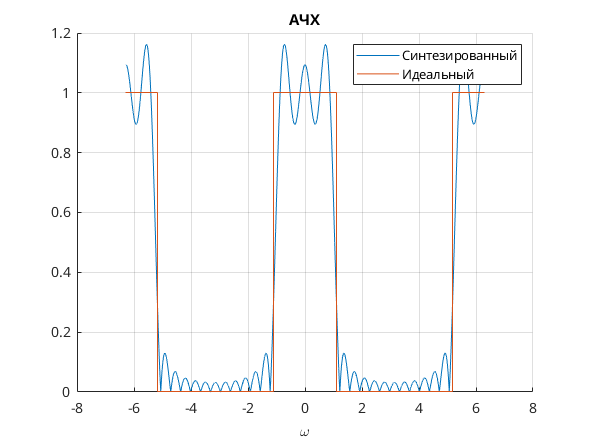

figure;
grid on;
hold on;
title('АЧХ');
xlabel('\omega');
plot(w, abs(A));
stairs(w, A_ideal);
legend("Синтезированный", "Идеальный");

АЧХ в дб

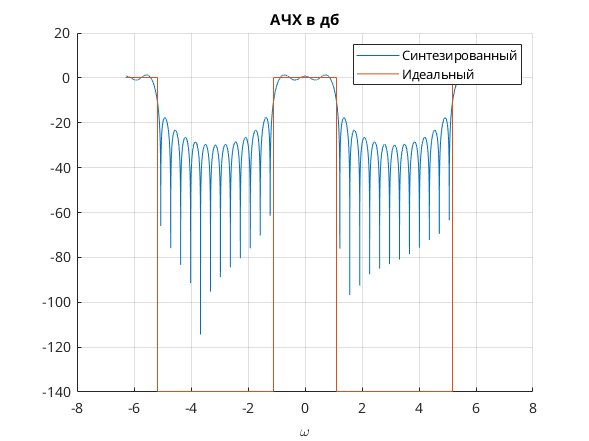

figure;
grid on;
hold on;
title('АЧХ в дб');
xlabel('\omega');
plot(w, db(abs(A)));
stairs(w, db(A_ideal));
legend("Синтезированный", "Идеальный");

ФЧХ

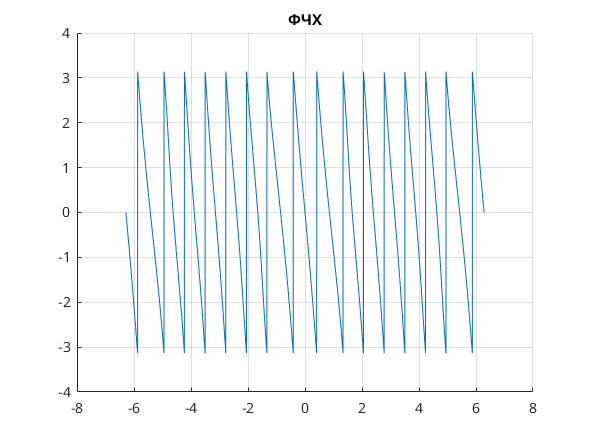

figure;
grid on;
hold on;
title('ФЧХ');
[ans_fchh, w_fchh] = freqz(h, 1, w);
plot(w_fchh, angle(ans_fchh));

## Задание 2

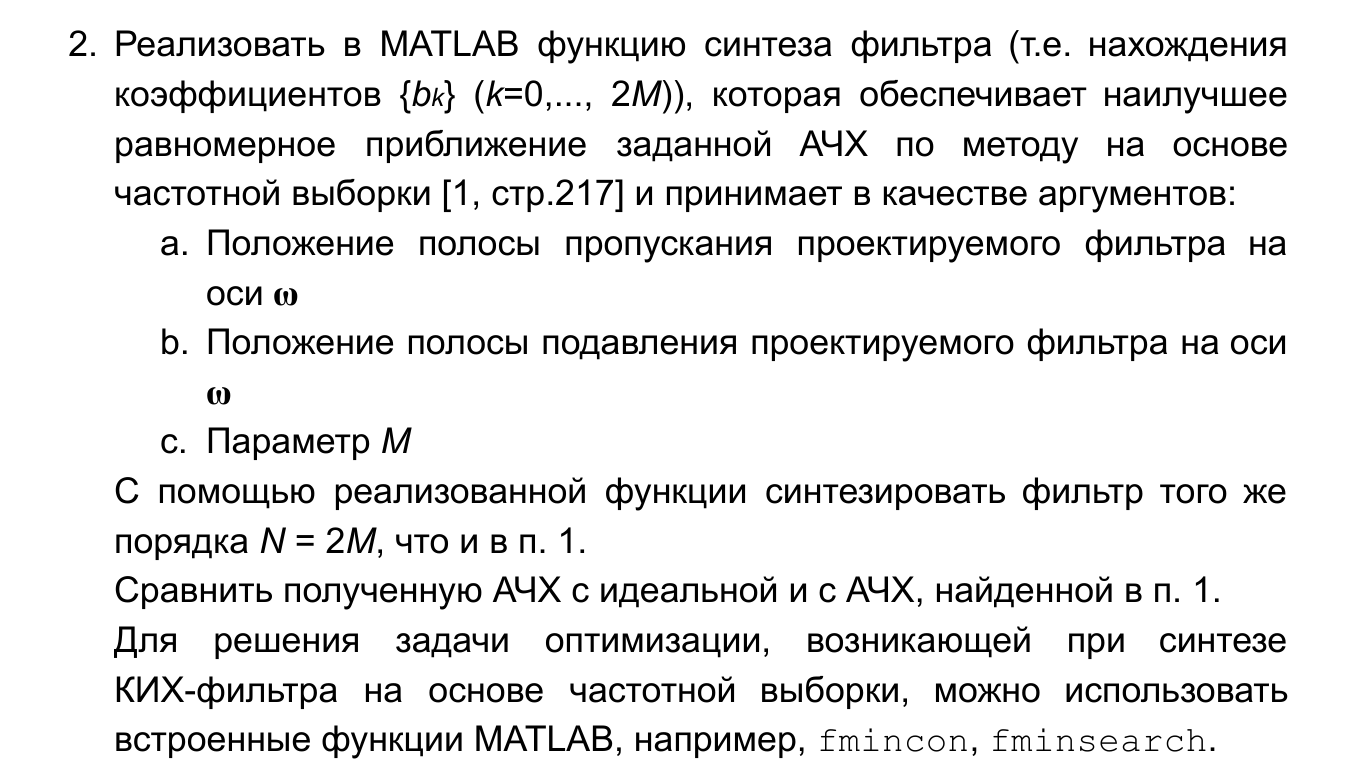

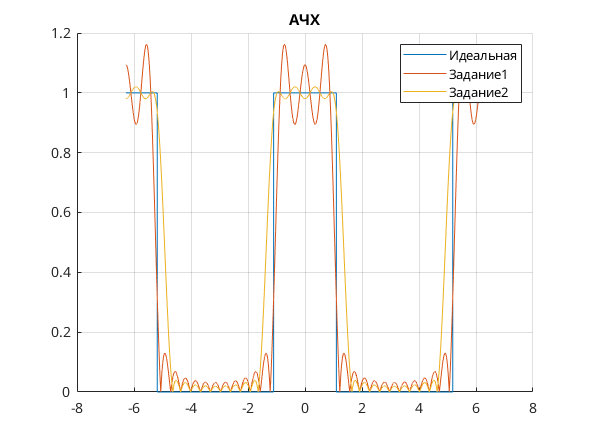

pass = [0 0.35*pi];
shrink = [0.5*pi pi];
M = 8;
h = get_h(Filter2(pass, shrink, M), M);
figure
grid on
hold on
plot(w, A_ideal)
plot(w, abs(A))
plot(w, Filter1(w,h,M))

legend('Идеальная', 'Задание1', 'Задание2')
title('АЧХ')

Наш новый фильтр получился с более равномерной полосой АЧХ в полосе пропускания и подовления.

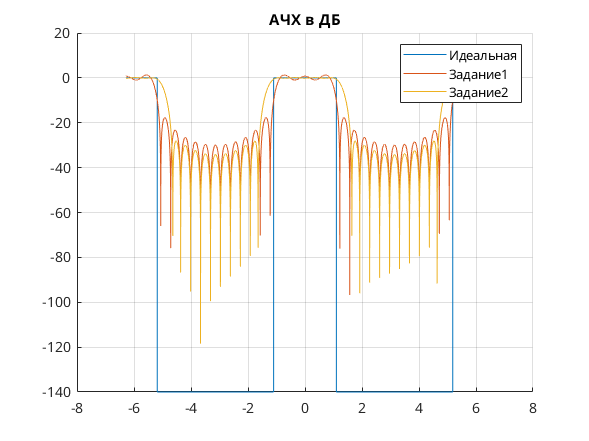

figure
hold on
grid on
plot(w, db(A_ideal))
plot(w, db(abs(A)))
plot(w, db(Filter1(w,h,M)))

legend('Идеальная', 'Задание1', 'Задание2')
title('АЧХ в ДБ')

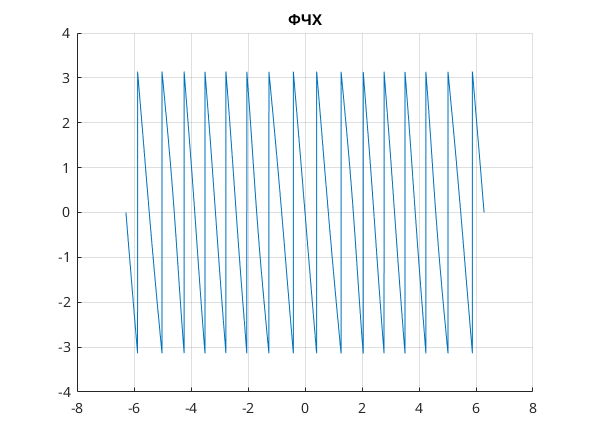

figure
grid on
hold on
plot(w, angle(freqz(h,1,w)))
title('ФЧХ')

## Задание 3

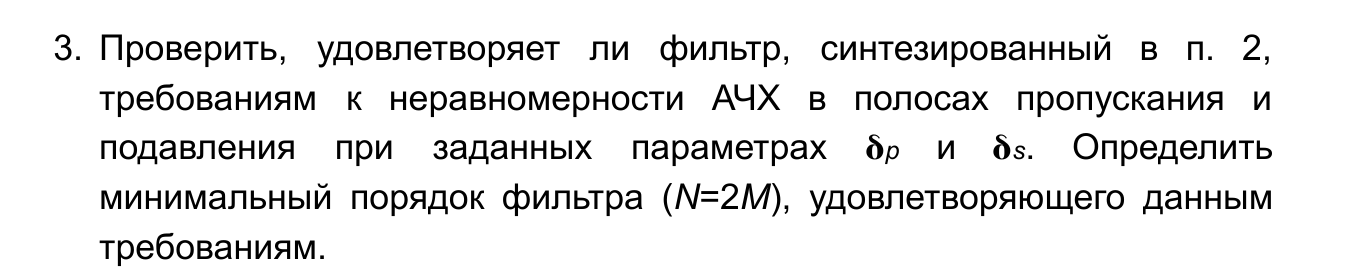

delta_p = zeros(1,8);
delta_s = zeros(1,8);
KD = @(w) (abs(w)<=(0.35*pi)).*(abs(w)>0);
for M = 8:15
    kd = Filter2(pass, shrink, M);
    h = get_h(kd,M);
    delta_p(M-7) = max(abs(Filter1(w, h, M) - KD(w)) .* (abs(w) > pass(1)) .* (abs(w) < pass(2)));
    delta_s(M-7) = max(abs(Filter1(w, h, M) - KD(w)) .* (abs(w) > shrink(1)) .* (abs(w) < shrink(2)));
end
sigma_p = 0.0075;
sigma_s = 0.03;

delta_p

delta_p =     0.0647    0.0735    0.0490    0.0431    0.0194    0.0241    0.0113    0.0071


delta_p<sigma_p

ans = 1×8 logical array
   0   0   0   0   0   0   0   1



delta_s

delta_s =     0.0768    0.0576    0.0617    0.0367    0.0518    0.0255    0.0310    0.0216


delta_s<sigma_s

ans = 1×8 logical array
   0   0   0   0   0   1   0   1


Фильтр при N = 16, не удовлетворяет условиям, нужен минимум 30 порядок.

## Задание 4

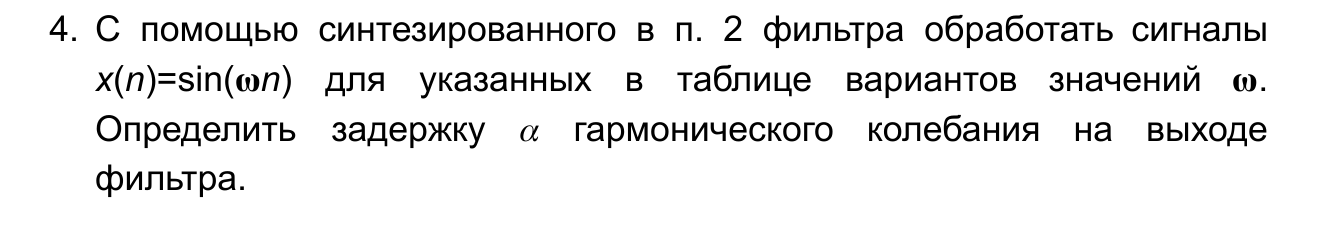

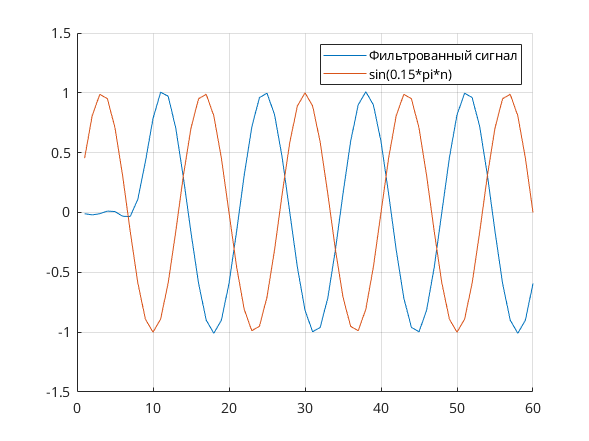

M = 8;
kd = Filter2(pass, shrink, M);
w = zeros(1,M+1);
for i = 0:1:M
    w(i+1) = pi/(M+1)*(i+0.5);
end
hv = @(k) 1/(M+1) * sum(kd.*cos(w*k));
h = zeros(1,2*M+2);

for k = 0:1:M
    h(M+1-k) = hv(k);
    h(M+1+k) = hv(k);
end
f1 = @(n) sin(0.15 * pi*n);
f2 = @(n) sin(0.3 * pi*n);
P = 60;
figure
grid on
hold on
plot(1:1:P,filter(h,1,f1(1:1:P)))

plot(1:1:P,f1((1:1:P)))
legend('Фильтрованный сигнал', 'sin(0.15*pi*n)')

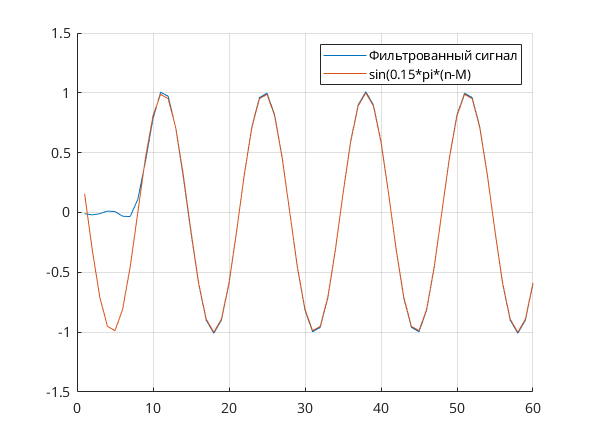

figure
grid on
hold on
plot(1:1:P,filter(h,1,f1(1:1:P)))
plot(1:1:P,f1((1:1:P)-M))
legend('Фильтрованный сигнал', 'sin(0.15*pi*(n-M)')

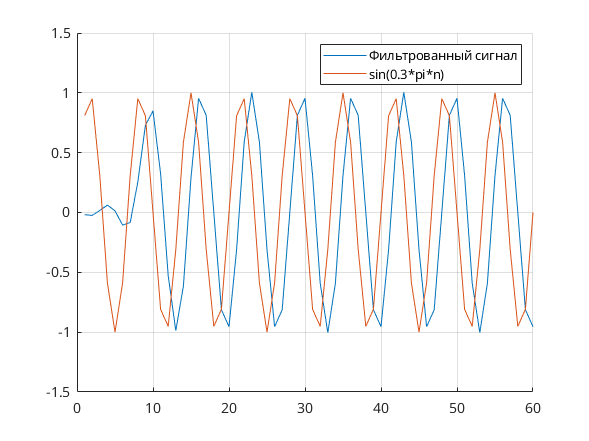

figure
grid on
hold on
plot(1:1:P,filter(h,1,f2(1:1:P)))
plot(1:1:P,f2((1:1:P)))
legend('Фильтрованный сигнал', 'sin(0.3*pi*n)')

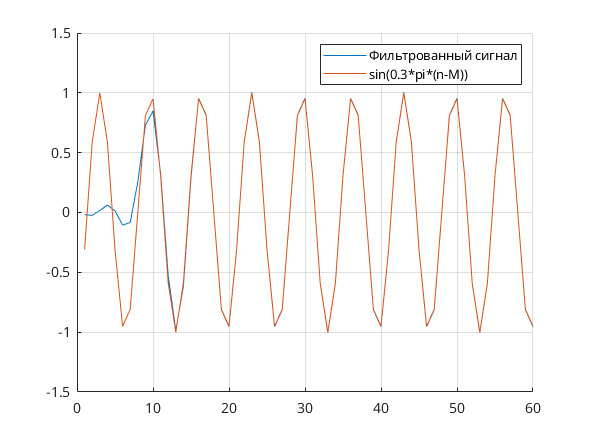

figure
grid on
hold on
plot(1:1:P,filter(h,1,f2(1:1:P)))
plot(1:1:P,f2((1:1:P)-M))
legend('Фильтрованный сигнал', 'sin(0.3*pi*(n-M))')

Сигналы из полосы пропускания получают задержку в M отсчетов, т.к данный фильтр имеет фазу $\phi(\omega) = -M\omega + 2\pi m$, а задержка сигнала $a = - \frac{d\phi(\omega)}{d\omega} = M$

## Задание 5

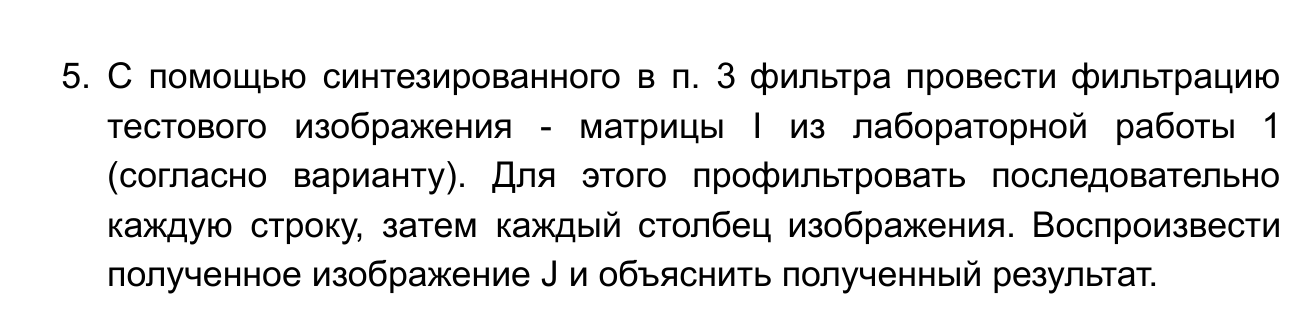

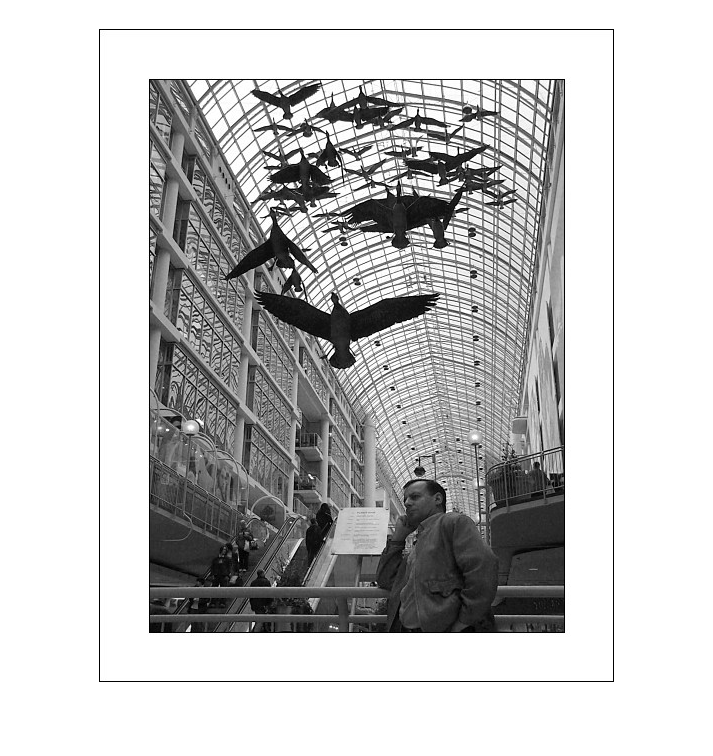

pass = [0 0.35*pi];
shrink = [0.5*pi pi];

M = 8;
K_d = Filter2(pass, shrink, M);
w = zeros(1, M+1);

for i = 0:1:M
    w(i+1) = pi/(M+1)*(i+0.5);
end

h_h = @(k) 1/(M+1) * sum(K_d.*cos(w*k));
h = zeros(1,2*M+2);

for k = 0:1:M
    h(M+1-k) = h_h(k);
    h(M+1+k) = h_h(k);
end

figure;
im = imread('./../img/var9.png');
imshow(im);

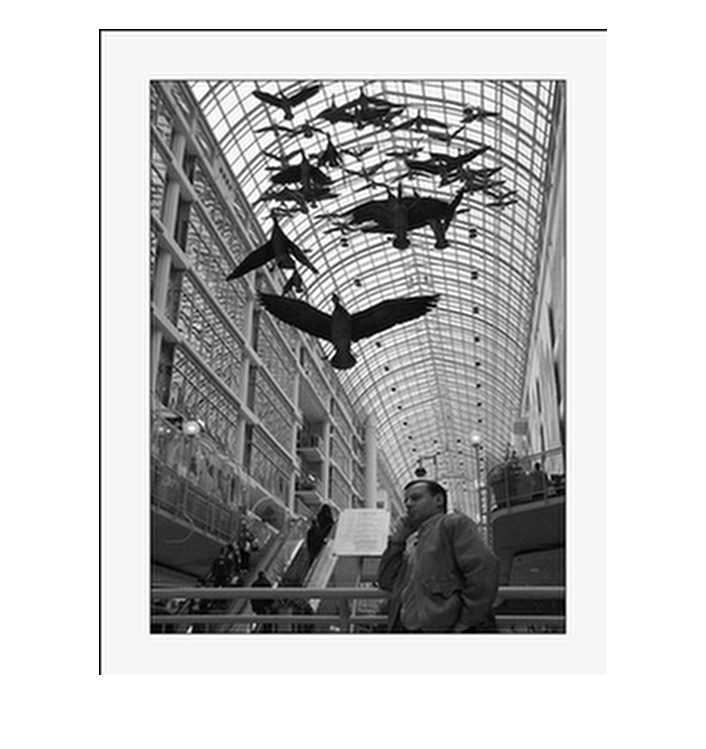

filtered_im = zeros(size(im));
filtered_im1 = zeros(size(im));

for i = 1:1:size(im,1)
    filtered_im(i,:) = filter(h,1,im(i,:));
end

for i = 1:1:size(im,2)
    filtered_im1(:,i) = filter(h,1,filtered_im(:,i));
end

filtered_im1 = filtered_im1(M:end, M:end);
im(M:end, M:end);
im = im(M:end, M:end);

figure;
imshow(uint8(filtered_im1));

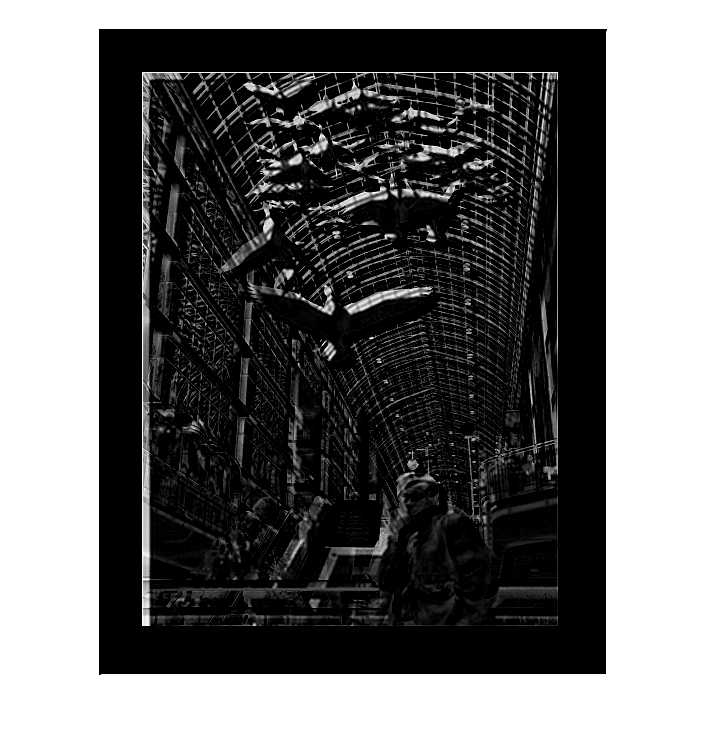

%compare result
compare = uint8(filtered_im1) - im;
figure;
imshow(uint8(compare));

У нас на разности изображений широкие границы из-за того, что на границе высокая частота, а у нас низкочастотный фильтр.

function x = f_min(par, pass, shrink, M)
    w = zeros(1,M+1);
    kd = zeros(size(w));
    j = 1;
    for i = 0:1:M
        w(i+1) = pi/(M+1)*(i+0.5);
        if (w(i+1)>pass(1) && w(i+1)<pass(2))
            kd(i+1) = 1;
        elseif (w(i+1)>shrink(1) && w(i+1)<shrink(2))
            kd(i+1) = 0;
        else
            kd(i+1) = par(j);
            j = j+1;
        end
    end
    KD = @(w) (w<=(0.35*pi)).*(w>0);
    hv = @(k) 1/(M+1) .* sum(kd.*cos(w.*k));
    h = zeros(1,M+1);
    for k = 0:1:M
        h(M+1-k) = hv(k);
    end
    w1 = 0:pi/100:pi;
    res = Filter1(w1,h,M);
    x = 0;
    for i = 1:1:length(w1)
        if (w1(i)>pass(1) && w1(i)<pass(2)) || (w1(i)>shrink(1) && w1(i)<shrink(2))
            x = max(x, abs(KD(w1(i)) - res(i)));
        end
    end
end

function res = Filter2(pass, shrink, M)
    w = zeros(1,M+1);
    kd = zeros(size(w));
    par = 0;
    j = 1;
    for i = 0:1:M
        w(i+1) = pi/(M+1)*(i+0.5);
        if (w(i+1)>pass(1) && w(i+1)<pass(2))
            kd(i+1) = 1;
        elseif (w(i+1) > shrink(1) && w(i+1) < shrink(2))
            kd(i+1) = 0;
        else
            par(j) = 0.1;
            j = j+1;
        end
    end
    res = fminsearch(@(x) f_min(x,pass,shrink, M), par);
    j = 1;
    for i = 0:1:M
        if (w(i+1)>pass(1) && w(i+1)<pass(2))
            kd(i+1) = 1;
        elseif (w(i+1)>shrink(1) && w(i+1)<shrink(2))
            kd(i+1) = 0;
        else
            kd(i+1) = res(j);
            j = j+1;
        end
    end
    res = kd;
end

function res = Filter1(w,h,M)
    res = h(M+1);
    for k=1:1:M
        res = res + 2*h(M+1-k)*cos(w*k);
    end
    res = abs(res);
end

function h = get_h(KD, M)
    w = zeros(1,M+1);
    for i = 0:1:M
        w(i+1) = pi/(M+1)*(i+0.5);
    end
    hv = @(k) 1/(M+1) * sum(KD.*cos(w*k));
    h = zeros(1,M+1);
    for k = 0:1:M
        h(M+1-k) = hv(k);
    end
end